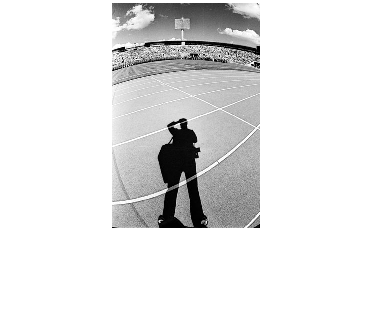

%TASK-1-PART-1-----------------------------------------
clear; clc;
%Входные-параметры-для-генерации-сигнала
t_min  = 0;
t_max  = 1;
t_step = 10^(-3);
nu = [20, 67];

%Генерация-сигнала
signal = GenerateSignal(t_min,t_max,t_step,nu);

%TASK-1-PART-2-----------------------------------------
F_max = max(nu(2),nu(1));

%TASK-1-PART-3-----------------------------------------
figure(2);
GenerateSignal(t_min,t_max,t_step,nu);
[dot_50, samp_signal_50] = SignalSamp(50,t_min,t_max,nu);
figure(3)
FourierTransformSamp(samp_signal_50, 50, F_max);

figure(4);
GenerateSignal(t_min,t_max,t_step,nu);
[dot_135, samp_signal_135] = SignalSamp(135,t_min,t_max,nu);
figure(5)
FourierTransformSamp(samp_signal_135, 135, F_max);

figure(6);
GenerateSignal(t_min,t_max,t_step,nu);
[dot_200, samp_signal_200] = SignalSamp(200,t_min,t_max,nu);
figure(7)
FourierTransformSamp(samp_signal_200, 200, F_max);

%TASK-1-PART-4-----------------------------------------
figure(8)
hold on; grid on;
plot([t_min: t_step: t_max], signal);
plot(dot_50, samp_signal_50, '.m')
alternative_signal = KotelnikovSeries(samp_signal_50, t_min, t_max, t_step, 50);

%TASK-1-PART-5-----------------------------------------
image = imread('var1.png');

figure(10)
BruteForceGouging(image, 2);

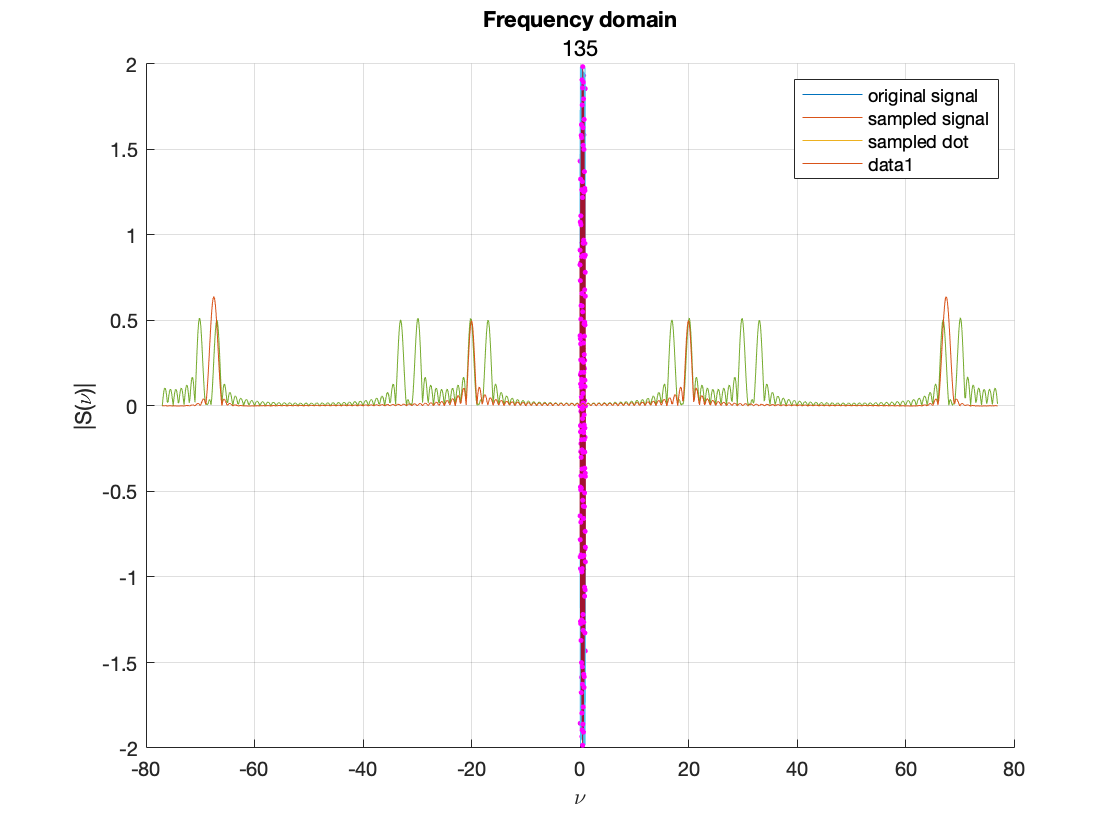

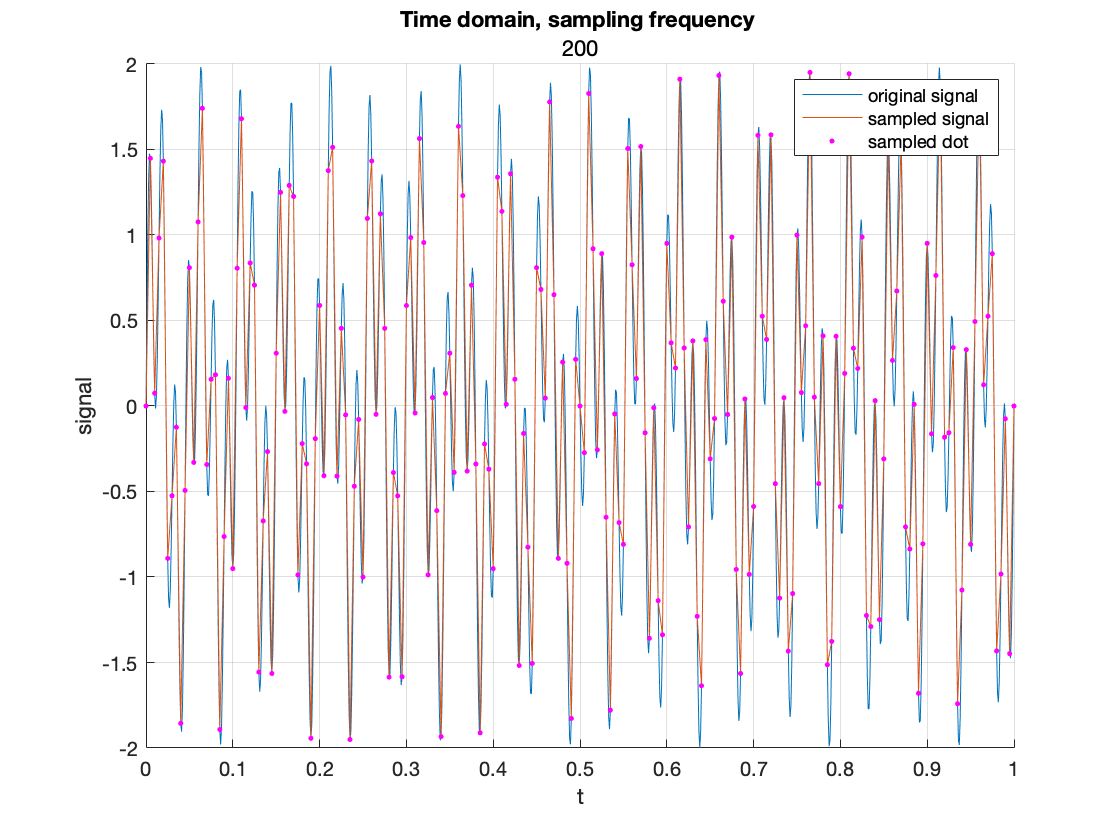

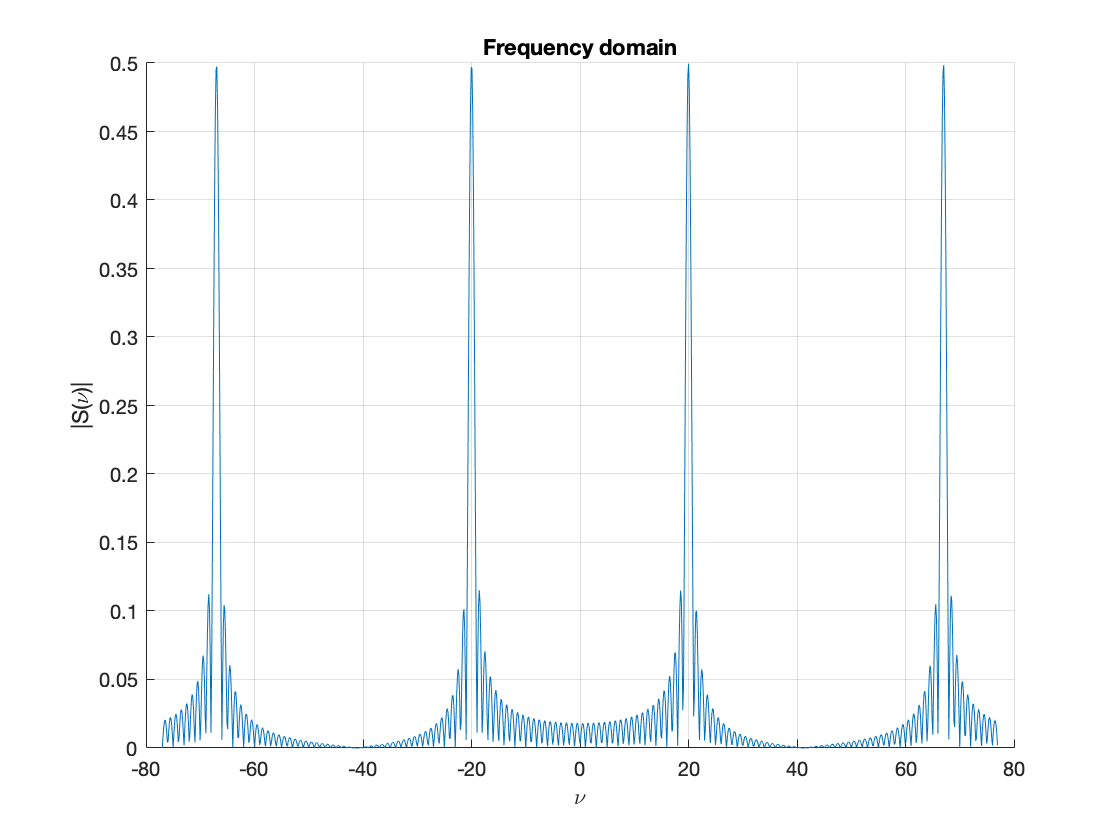

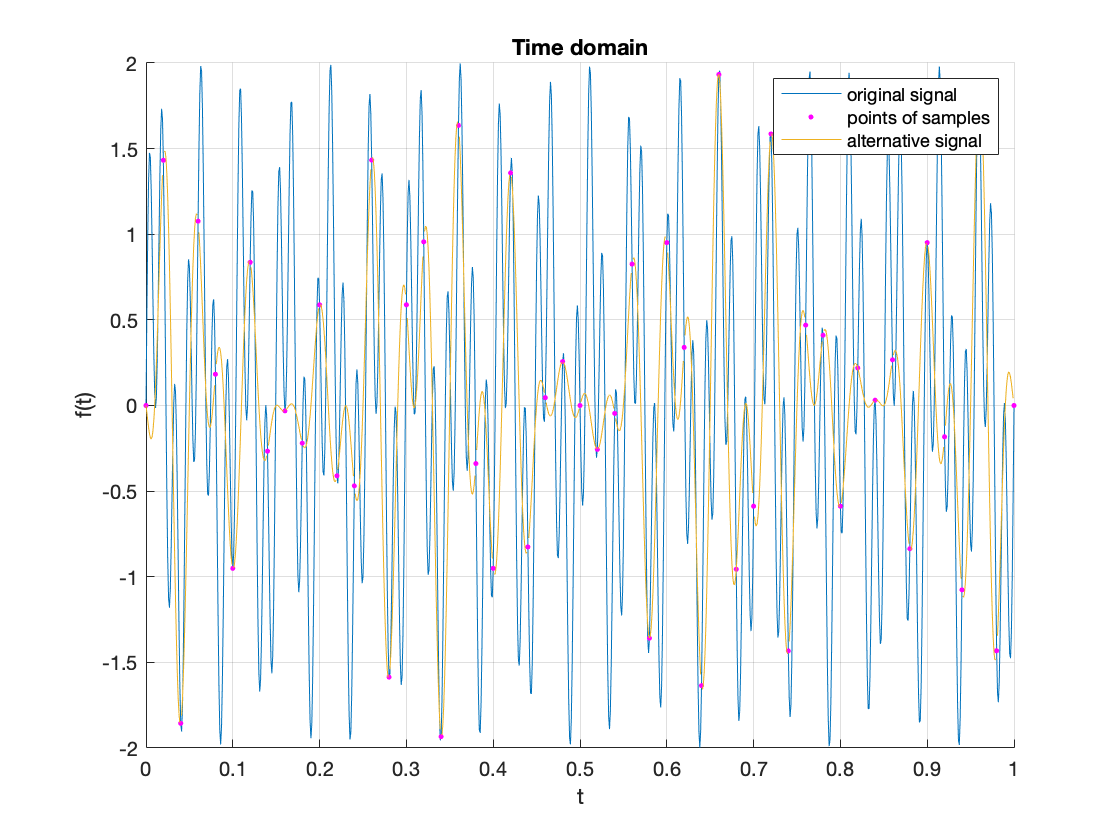

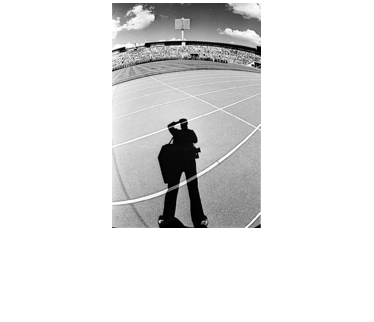

im2 = imresize(image, 1./2);
figure(11)
imshow(im2)

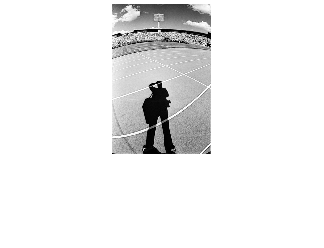


figure(12)
BruteForceGouging(image, 3);

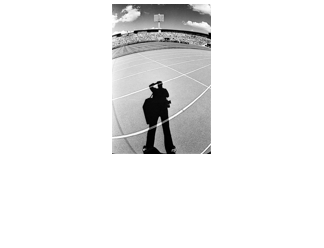

im3 = imresize(image, 1./3);
figure(13)
imshow(im3)

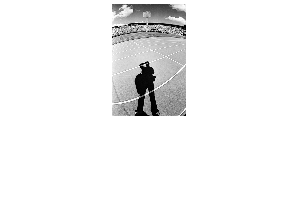


figure(14)
BruteForceGouging(image, 4);

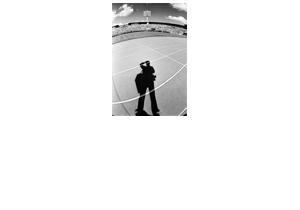

im4 = imresize(image, 1./4);
figure(15)
imshow(im4)